% Panda正运动学矩阵分析与仿真
%计算转换矩阵表达式
clear
clc

% syms:Create symbolic scalar variables and functions, and matrix variables and functions
syms q q1 q2 q3 q4 q5 q6 q7

% 改进DH
function [T] = cal_transform_matrix_modified(a_i_1, d, alpha_i_1, q)

T = [cos(q), -sin(q), 0, round(a_i_1,4);
     sin(q)*round(cos(alpha_i_1), 4), round(cos(alpha_i_1),4)*cos(q), -round(sin(alpha_i_1), 4), -round(sin(alpha_i_1)*d,4);
       round(sin(alpha_i_1),4)*sin(q), cos(q)*round(sin(alpha_i_1),4), round(cos(alpha_i_1),4), round(cos(alpha_i_1)*d,4);
       0,0,0,1];
end

%DH table: a, d, alpha, theta
DH = {0.0,   0.333, 0.0,   0.000000;
      0.0,	 0.0,   -pi/2, 0.000000;
      0.0,   0.316, pi/2,  0.000000;
      0.0825,0.0,   pi/2,  0.000000;
     -0.0825,0.384, -pi/2, 0.00000;
      0.0,   0.0,   pi/2,  deg2rad(28.6600000);
      0.088, 0.0,   pi/2,  0.000000;}

DH = 7×4 cell 数组
    {[      0]}    {[0.3330]}    {[      0]}    {[     0]}
    {[      0]}    {[     0]}    {[-1.5708]}    {[     0]}
    {[      0]}    {[0.3160]}    {[ 1.5708]}    {[     0]}
    {[ 0.0825]}    {[     0]}    {[ 1.5708]}    {[     0]}
    {[-0.0825]}    {[0.3840]}    {[-1.5708]}    {[     0]}
    {[      0]}    {[     0]}    {[ 1.5708]}    {[0.5002]}
    {[ 0.0880]}    {[     0]}    {[ 1.5708]}    {[     0]}


% theta = [0, 0, 0, 0, 0, 28.66*pi/180, 0]

% 计算矩阵表达式
T01 = cal_transform_matrix_modified(DH{1,1}, DH{1,2}, DH{1,3}, q1)

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{333}{1000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = cal_transform_matrix_modified(DH{2,1}, DH{2,2}, DH{2,3}, q2)

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(q_{2}\right) & -\cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = cal_transform_matrix_modified(DH{3,1}, DH{3,2}, DH{3,3}, q3)

$$T23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & 0\\ 0 & 0 & -1 & -\frac{79}{250}\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34 = cal_transform_matrix_modified(DH{4,1}, DH{4,2}, DH{4,3}, q4)

$$T34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & \frac{33}{400}\\ 0 & 0 & -1 & 0\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T45 = cal_transform_matrix_modified(DH{5,1}, DH{5,2}, DH{5,3}, q5)

$$T45 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & -\frac{33}{400}\\ 0 & 0 & 1 & \frac{48}{125}\\ -\sin\left(q_{5}\right) & -\cos\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T56 = cal_transform_matrix_modified(DH{6,1}, DH{6,2}, DH{6,3}, q6)

$$T56 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(q_{6}\right) & \cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T67 = cal_transform_matrix_modified(DH{7,1}, DH{7,2}, DH{7,3}, q7)

$$T67 = \left(\begin{array}{cccc} \cos\left(q_{7}\right) & -\sin\left(q_{7}\right) & 0 & \frac{11}{125}\\ 0 & 0 & -1 & 0\\ \sin\left(q_{7}\right) & \cos\left(q_{7}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T07 = T01 * T12 * T23 * T34 * T45 * T56 * T67



T01 = cal_transform_matrix_modified(DH{1,1}, DH{1,2}, DH{1,3}, DH{1,4});
T12 = cal_transform_matrix_modified(DH{2,1}, DH{2,2}, DH{2,3}, DH{2,4});
T23 = cal_transform_matrix_modified(DH{3,1}, DH{3,2}, DH{3,3}, DH{3,4});
T34 = cal_transform_matrix_modified(DH{4,1}, DH{4,2}, DH{4,3}, DH{4,4});
T45 = cal_transform_matrix_modified(DH{5,1}, DH{5,2}, DH{5,3}, DH{5,4});
T56 = cal_transform_matrix_modified(DH{6,1}, DH{6,2}, DH{6,3}, DH{6,4});
T67 = cal_transform_matrix_modified(DH{7,1}, DH{7,2}, DH{7,3}, DH{7,4});

% 末端执行器中心的位置和姿态
T07 =  T01 * T12 * T23 * T34 * T45 * T56 * T67

T07 =     0.8775         0    0.4796    0.0772
         0   -1.0000         0         0
    0.4796         0   -0.8775    1.0752
         0         0         0    1.0000


% 仿真验证
%建立机器人模型
%'standard': 标准模式,'modified'改进模式，不写默认标准模式
rbt_mode='modified';
L=cell(1,7);
for i=1:7
    L{i}=Link([DH{i,4} DH{i,2} DH{i,1} DH{i,3} DH{i,4}],rbt_mode);
end
view(3)
robot1=SerialLink([L{1} L{2} L{3} L{4} L{5} L{6},L{7}],'name','Panda');
%target = robot.fkine([0,0, 0 , 0, deg2rad(30), deg2rad(28.66),0])  %求解特定角度下末端相对于基坐标的姿态
%连接连杆，机器人取名Panda
theta=zeros(1,7);
for i=1:7
    theta(i)=DH{i,4};
end
robot1.offset=theta;
robot1.display();

 
robot1 = 
 
Panda:: 7 axis, RRRRRRR, modDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.333|          0|          0|          0|
|  2|         q2|          0|          0|    -1.5708|          0|
|  3|         q3|      0.316|          0|     1.5708|          0|
|  4|         q4|          0|     0.0825|     1.5708|          0|
|  5|         q5|      0.384|    -0.0825|    -1.5708|          0|
|  6|         q6|          0|          0|     1.5708|   0.500211|
|  7|         q7|          0|      0.088|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


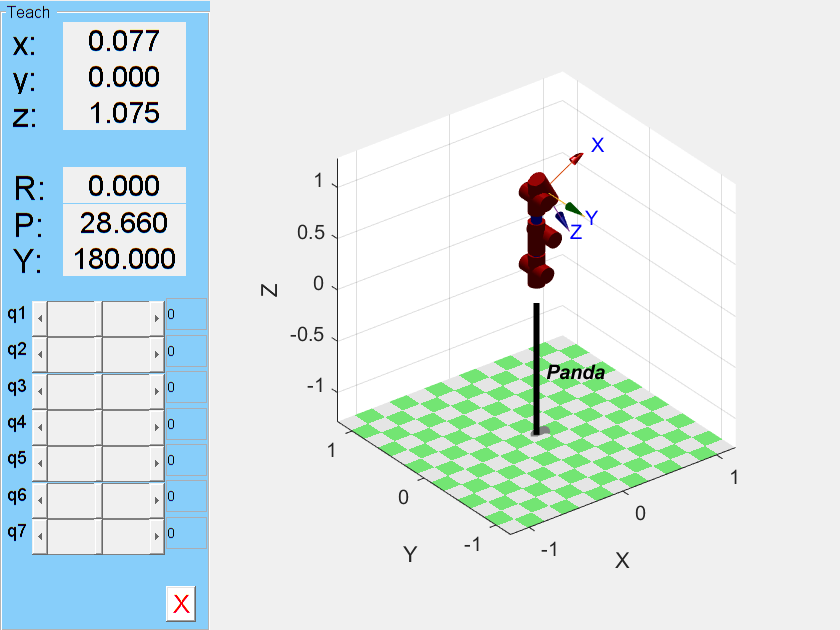

robot1.teach();

% Panda逆运动学矩阵分析与仿真

%建立机器人模型
%'standard': 标准模式,'modified'改进模式，不写默认标准模式
rbt_mode='modified';
L=cell(1,7);
for i=1:7
    L{i}=Link([DH{i,4} DH{i,2} DH{i,1} DH{i,3} DH{i,4}],rbt_mode);
end
robot2=SerialLink([L{1} L{2} L{3} L{4} L{5} L{6},L{7}],'name','Panda');

% 通过正运动学计算一个位姿
target_pose = T07

target_pose =     0.8775         0    0.4796    0.0772
         0   -1.0000         0         0
    0.4796         0   -0.8775    1.0752
         0         0         0    1.0000


% robot2：机器人
% target_pose：目标位姿
n = robot2.n;

% 检查矩阵
%TT = SE3.check(target_pose)
TT = target_pose;

%  set default parameters for solution
opt.ilimit = 500; %maximum number of iterations (default 500)
opt.rlimit = 100; %maximum number of consecutive step rejections (default 100)
opt.slimit = 100; %maximum number of search attempts (default 100)
opt.tol = 1e-10; %final error tolerance (default 1e-10)
opt.lambda = 0.1; %initial value of lambda (default 0.1)
opt.lambdamin = 0;%minimum allowable value of lambda (default 0)
opt.quiet = false;%be quiet
opt.mask = [1 1 1 1 1 1];%mask vector (6x1) that correspond to translation in X, Y and Z, and rotation about X, Y and Z respectively.
opt.q0 = zeros(1, n);%initial joint configuration (default all zeros)
opt.transpose = NaN;%use Jacobian transpose with step size A, rather than Levenberg-Marquadt

assert(numel(opt.mask) == 6, 'RTB:ikine:badarg', 'Mask matrix should have 6 elements');
assert(n >= numel(find(opt.mask)), 'RTB:ikine:badarg', 'Number of robot DOF must be >= the same number of 1s in the mask matrix');

% 创建对角矩阵
W = diag(opt.mask);

qt = zeros(length(TT), n);  % preallocate space for results
tcount = 0;              % total iteration count
rejcount = 0;            % rejected step count

q = opt.q0;

failed = false;
revolutes = robot2.isrevolute();

T = TT;
lambda = opt.lambda;

iterations = 0;

while true
    % update the count and test against iteration limit
    iterations = iterations + 1;
    if iterations > opt.ilimit
        if ~opt.quiet
            warning('ikine: iteration limit %d exceeded (pose %d), final err %g', ...
                opt.ilimit, i, nm);
        end
        failed = true;
        break
    end
    % 计算误差，e=(dx, dy, dz, dRx, dRy, dRz)
    e = tr2delta(robot2.fkine(q), T);
    
    % are we there yet。norm:向量范数和矩阵范数
    if norm(W*e) < opt.tol
        break;
    end
    
    % compute the Jacobian
    J = jacobe(robot2, q);

    % do the damped inverse Gauss-Newton with Levenberg-Marquadt
    JtJ = J'*W*J; %J'：矩阵的转置
    % inv(X)：计算X的逆矩阵；eye:构建单位矩阵
    dq = inv(JtJ + (lambda + opt.lambdamin) * eye(size(JtJ)) ) * J' * W * e;
    
    % compute possible new value of
    qnew = q + dq';
    
    % and figure out the new error
    enew = tr2delta(robot2.fkine(qnew), T);
    
    % was it a good update?
    if norm(W*enew) < norm(W*e)
        q = qnew;
        e = enew;
        lambda = lambda/2;
        rejcount = 0;
    else
        % step is rejected, increase the damping and retry
        lambda = lambda*2;
        rejcount = rejcount + 1;
        if rejcount > opt.rlimit
            if ~opt.quiet
                warning('ikine: rejected-step limit %d exceeded (pose %d), final err %g', ...
                    opt.rlimit, i, norm(W*enew));
            end
            failed = true;
            break;
        end
        continue;  % try again
    end
    % wrap angles for revolute joints
    k = (q > pi) & revolutes;
    q(k) = q(k) - 2*pi; % 大于180的，取另一侧
    
    k = (q < -pi) & revolutes; %小于-180的，取另一侧
    q(k) = q(k) + 2*pi;
    
    %norm:向量范数和矩阵范数
    nm = norm(W*e);

end  % end ikine solution for this pose
qt(i,:) = q';
q_result = q'

q_result =    -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.5002
    0.0000


tcount = tcount + iterations;

if failed
    if ~opt.quiet
        warning('failed to converge: try a different initial value of joint coordinates');
    end
    qt = [];
    q_result=[];
end

% %验证逆解结果
%ik_result = robot2.fkine(q_result)

T01 = cal_transform_matrix_modified(DH{1,1}, DH{1,2}, DH{1,3}, q_result(1,1));
T12 = cal_transform_matrix_modified(DH{2,1}, DH{2,2}, DH{2,3}, q_result(2,1));
T23 = cal_transform_matrix_modified(DH{3,1}, DH{3,2}, DH{3,3}, q_result(3,1));
T34 = cal_transform_matrix_modified(DH{4,1}, DH{4,2}, DH{4,3}, q_result(4,1));
T45 = cal_transform_matrix_modified(DH{5,1}, DH{5,2}, DH{5,3}, q_result(5,1));
T56 = cal_transform_matrix_modified(DH{6,1}, DH{6,2}, DH{6,3}, q_result(6,1));
T67 = cal_transform_matrix_modified(DH{7,1}, DH{7,2}, DH{7,3}, q_result(7,1));
T07 = T01 * T12 * T23 * T34 * T45 * T56 * T67

T07 =     0.8775    0.0000    0.4796    0.0772
   -0.0000   -1.0000    0.0000    0.0000
    0.4796   -0.0000   -0.8775    1.0752
         0         0         0    1.0000
